clear

freq = 95000;
Fs = freq*2.5;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1200000;             % Length of signal
t = (0:L-1)*T;        % Time vector

S = sin(2*pi*5000*t) + sin(2*pi*95000*t)+ sin(2*pi*60000*t)+ sin(2*pi*20000*t);
%plot(S)
S

S =          0    2.2243    0.1488    1.3386    0.8379    2.0867    1.1686   -1.6782    1.0672    0.3309   -0.0324    0.1510    0.3120    3.4777    1.0455    0.9430    2.5227    1.2054    1.2481   -1.5388   -0.1151    0.8906   -1.8766   -0.2650   -0.1025    1.3654    0.8063   -1.2809    1.6435    0.0153   -1.3763   -1.7423   -2.2738   -0.1180   -2.8555   -2.1585    0.3468   -0.4509    0.3633   -1.3120    0.5128    0.9022   -2.4855   -1.0567   -1.3301   -0.5584   -1.0116   -1.9916    1.9916    1.0116


Y = fft(S)

Y = 1.0e+05 *

   0.0001 + 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i


P2 = abs(Y/L)

P2 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


P1 = P2(1:L/2+1)

P1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


P1(2:end-1) = 2*P1(2:end-1)

P1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



f = Fs*(0:(L/2))/L;

plot(f,P1) 
title('Input signal in the frequency domain')
xlabel('f (Hz)')
ylabel('Amplitude')


output(1:1200000) = 0

output =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%output(1:119993) = 0.0046*S(5:119997) - 0.0184*S(4:119996) + 0.0276*S(3:119995) - 0.0184*S(2:119994) + 0.0046*S(1:119993) -2.6244*output(4:119996) -2.9710*output(3:119995) - 1.6411*output(2:119994)- 0.3702*output(1:119993)
%output(1:119993) = 0.0033*S(5:119997) - 0.0131*S(4:119996) + 0.0179*S(3:119995) - 0.0131*S(2:119994) + 0.0033*S(1:119993) -2.7711*output(4:119996) -3.2183*output(3:119995) - 1.7975*output(2:119994)- 0.4042*output(1:119993)
for k = 5:1200000
    output(k) = 0.0046*S(k)- 0.0184*S(k-1) + 0.0276*S(k-2) - 0.0184*S(k-3) + 0.0046*S(k-4) -2.6244*output(k-1) -2.9710*output(k-2) - 1.6411*output(k-3) - 0.3702*output(k-4);
end
output

output =          0         0         0         0   -0.0576    0.1898   -0.3608    0.4966   -0.4881    0.2510    0.1695   -0.5903    0.8109   -0.7290    0.3564    0.1943   -0.7120    0.9583   -0.8097    0.3356    0.2675   -0.7787    1.0037   -0.8310    0.3134    0.3270   -0.8251    1.0048   -0.8105    0.3007    0.3412   -0.8492    1.0124   -0.7866    0.2758    0.3392   -0.8394    1.0176   -0.7895    0.2590    0.3529   -0.8271    1.0012   -0.7951    0.2692    0.3615   -0.8373    0.9898   -0.7807    0.2776


f

f = 1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


L = 1200000

L = 1200000

Y2 = fft(output)

Y2 = 1.0e+05 *

  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i


P4 = abs(Y2/L)

P4 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


P3 = P4(1:(L/2+1))

P3 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


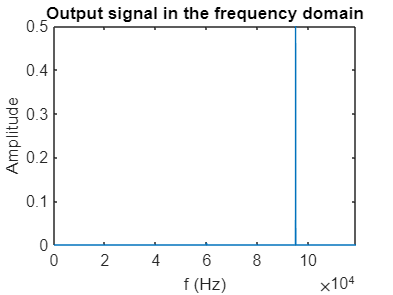

%P3(2:end-1) = 2*P3(2:end-1)

plot(f, P3)
title('Output signal in the frequency domain')
xlabel('f (Hz)')
ylabel('Amplitude')



%out[k] = 0.0046*x[k] - 0.0184*x[k-1] + 0.0276*x[k-2] - 0.0184*x[k-3] + 0.0046*x[k-4] -2.6244*out[k-1] -2.9710*out[k-2] - 1.6411*out[k-3] - 0.3702*out[k-4]